clear variables
load('Tests/coupled_tline/coupled_tl_28par_10std.mat')
[~,d] = size(training_samples);


training_samples = training_samples(1:870,:);
vouts_train = vouts_train(1:870,:);
m = 2;

tic
vouts_total2 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total2-vouts,"fro")/norm(vouts,"fro")

ans = 0.0299

toc

Elapsed time is 0.895895 seconds.


training_samples = training_samples2(1:8990,:);
vouts_train = vouts_train2(1:8990,:);
m = 3;

tic
vouts_total3 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total3-vouts,"fro")/norm(vouts,"fro")

ans = 0.0130

toc

Elapsed time is 20.226381 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_Newton,PC_coefficients_TT,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-Newton',0.3,0.2,r);

ans =     0.0073    0.0087    9.0000


ans =     0.0083    0.0095    1.0000


ans =     0.0057    0.0076    2.0000


ans =     0.0047    0.0068    2.0000


ans =     0.0073    0.0090    1.0000


ans =     0.0062    0.0085    2.0000


ans =     0.0053    0.0074    2.0000


ans =     0.0047    0.0060    2.0000


ans =     0.0084    0.0099    1.0000


ans =     0.0060    0.0077    2.0000


ans =     0.0054    0.0071    2.0000


ans =     0.0095    0.0094    1.0000


ans =     0.0063    0.0069    2.0000


ans =     0.0086    0.0078    1.0000


ans =     0.0058    0.0068    2.0000


ans =     0.0083    0.0083    1.0000


ans =     0.0055    0.0065    2.0000


ans =     0.0075    0.0076    1.0000


ans =     0.0057    0.0070    2.0000


ans =     0.0048    0.0061    2.0000


ans =     0.0051    0.0063    2.0000


ans =     0.0056    0.0065    2.0000


ans =     0.0065    0.0075    2.0000


ans =     0.0066    0.0072    2.0000


ans =     0.0061    0.0066    2.0000


ans =     0.0094    0.0089    1.0000


ans =     0.0061    0.0074    2.0000


ans =     0.0056    0.0074    2.0000


ans =     0.0054    0.0073    2.0000


ans =     0.0058    0.0078    2.0000


ans =     0.0069    0.0096    2.0000


ans =     0.0073    0.0090    2.0000


ans =     0.0068    0.0085    2.0000


ans =     0.0069    0.0079    2.0000


ans =     0.0067    0.0077    2.0000


ans =     0.0070    0.0086    2.0000


ans =     0.0073    0.0089    2.0000


ans =     0.0070    0.0083    3.0000


ans =     0.0072    0.0092    2.0000


ans =     0.0064    0.0081    3.0000


ans =     0.0074    0.0089    2.0000


ans =     0.0090    0.0092    2.0000


ans =     0.0085    0.0089    3.0000


ans =     0.0091    0.0095    2.0000


ans =     0.0091    0.0095    2.0000


ans =     0.0069    0.0093    3.0000


ans =     0.0061    0.0086    4.0000


ans =     0.0066    0.0086    5.0000


ans =     0.0084    0.0100    3.0000


ans =     0.0073    0.0092    3.0000


ans = 1×3
    0.0074    0.0098    2.0000


ans = 1×3
    0.0069    0.0090    3.0000


ans = 1×3
    0.0077    0.0098    2.0000


ans = 1×3
    0.0070    0.0089    3.0000


ans = 1×3
    0.0075    0.0092    2.0000


ans = 1×3
    0.0070    0.0086    3.0000


ans = 1×3
    0.0081    0.0096    2.0000


ans = 1×3
    0.0080    0.0099    3.0000


ans = 1×3
    0.0076    0.0096    5.0000


ans = 1×3
    0.0067    0.0130   20.0000


ans = 1×3
    0.0071    0.0135   12.0000


ans = 1×3
    0.0064    0.0119   11.0000


ans = 1×3
    0.0059    0.0095    4.0000


ans = 1×3
    0.0071    0.0094    2.0000


ans = 1×3
    0.0071    0.0096    4.0000


ans = 1×3
    0.0066    0.0103   12.0000


ans = 1×3
    0.0077    0.0134   11.0000


ans = 1×3
    0.0088    0.0140   13.0000


ans = 1×3
    0.0052    0.0118   28.0000


ans = 1×3
    0.0058    0.0096    4.0000


ans = 1×3
    0.0067    0.0099    4.0000


ans = 1×3
    0.0075    0.0095    4.0000


ans = 1×3
    0.0076    0.0097    5.0000


ans = 1×3
    0.0057    0.0094   12.0000


ans = 1×3
    0.0042    0.0125   18.0000


ans = 1×3
    0.0045    0.0150   10.0000


ans = 1×3
    0.0052    0.0169   11.0000


ans = 1×3
    0.0063    0.0192   11.0000


ans = 1×3
    0.0074    0.0204   11.0000


ans = 1×3
    0.0076    0.0202   14.0000


ans = 1×3
    0.0067    0.0172   12.0000


ans = 1×3
    0.0049    0.0118   12.0000


ans = 1×3
    0.0065    0.0097    2.0000


ans = 1×3
    0.0038    0.0100   11.0000


ans = 1×3
    0.0044    0.0172   11.0000


ans = 1×3
    0.0061    0.0223   13.0000


ans = 1×3
    0.0071    0.0205   11.0000


ans = 1×3
    0.0063    0.0193   13.0000


ans = 1×3
    0.0066    0.0221   12.0000


ans = 1×3
    0.0080    0.0230   13.0000


ans = 1×3
    0.0075    0.0173   12.0000


ans = 1×3
    0.0058    0.0126   12.0000


ans = 1×3
    0.0046    0.0114   12.0000


ans = 1×3
    0.0044    0.0118   11.0000


ans = 1×3
    0.0047    0.0161   12.0000


ans = 1×3
    0.0077    0.0310    3.0000


ans = 1×3
    0.0154    0.0626    2.0000


ans = 1×3
    0.0182    0.0735    5.0000


ans = 1×3
    0.0166    0.0562   18.0000


ans = 1×3
    0.0137    0.0351   13.0000


norm(vouts_Newton-vouts,"fro")/norm(vouts,"fro")

ans = 0.0130

toc

Elapsed time is 34.197914 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_ALS,PC_coefficients_ALS,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-ALS',0.3,0.2,r);

ans =     0.0044    0.0099  269.0000


ans =     0.0057    0.0098   26.0000


ans =     0.0062    0.0097   26.0000


ans =     0.0063    0.0098   27.0000


ans =     0.0056    0.0098   27.0000


ans =     0.0058    0.0098   27.0000


ans =     0.0056    0.0099   30.0000


ans =     0.0056    0.0099   27.0000


ans =     0.0048    0.0100   42.0000


ans =     0.0042    0.0099   73.0000


ans =     0.0037    0.0100   88.0000


ans =     0.0045    0.0100   54.0000


ans =     0.0048    0.0100   54.0000


ans =     0.0048    0.0100   53.0000


ans =     0.0043    0.0099   73.0000


ans =     0.0042    0.0099   71.0000


ans =     0.0046    0.0098   43.0000


ans =     0.0057    0.0097   24.0000


ans =     0.0050    0.0100   30.0000


ans =     0.0049    0.0100   33.0000


ans =     0.0052    0.0099   49.0000


ans =     0.0041    0.0099  106.0000


ans =     0.0033    0.0100  167.0000


ans =     0.0033    0.0100  162.0000


ans =     0.0036    0.0100  108.0000


ans =     0.0038    0.0096   78.0000


ans =     0.0045    0.0100   48.0000


ans =     0.0052    0.0099   49.0000


ans =     0.0043    0.0097   78.0000


ans =     0.0039    0.0098   80.0000


ans =     0.0037    0.0100  121.0000


ans =     0.0044    0.0115   88.0000


ans =     0.0040    0.0100   88.0000


ans =     0.0039    0.0100   97.0000


ans =     0.0039    0.0098  103.0000


ans =     0.0043    0.0104   88.0000


ans =     0.0045    0.0100   99.0000


ans =     0.0048    0.0099  105.0000


ans =     0.0050    0.0099  105.0000


ans =     0.0052    0.0100  104.0000


ans =     0.0042    0.0097  157.0000


ans =     0.0043    0.0117  168.0000


ans =     0.0044    0.0131  196.0000


ans =     0.0043    0.0125  196.0000


ans =     0.0040    0.0100  157.0000


ans =     0.0042    0.0097  101.0000


ans =     0.0036    0.0100  141.0000


ans =     0.0043    0.0115  148.0000


ans =     0.0047    0.0119  168.0000


ans =     0.0045    0.0105  169.0000


ans = 1×3
    0.0045    0.0108  115.0000


ans = 1×3
    0.0042    0.0100  106.0000


ans = 1×3
    0.0040    0.0099  120.0000


ans = 1×3
    0.0037    0.0099  151.0000


ans = 1×3
    0.0042    0.0100  117.0000


ans = 1×3
    0.0047    0.0100  103.0000


ans = 1×3
    0.0049    0.0111  115.0000


ans = 1×3
    0.0044    0.0113  168.0000


ans = 1×3
    0.0050    0.0160  169.0000


ans = 1×3
    0.0053    0.0189  223.0000


ans = 1×3
    0.0049    0.0147  250.0000


ans = 1×3
    0.0044    0.0120  224.0000


ans = 1×3
    0.0036    0.0099  211.0000


ans = 1×3
    0.0038    0.0099  135.0000


ans = 1×3
    0.0039    0.0100  145.0000


ans = 1×3
    0.0048    0.0123  116.0000


ans = 1×3
    0.0052    0.0154  170.0000


ans = 1×3
    0.0056    0.0174  196.0000


ans = 1×3
    0.0051    0.0161  196.0000


ans = 1×3
    0.0046    0.0152  169.0000


ans = 1×3
    0.0047    0.0144  168.0000


ans = 1×3
    0.0048    0.0122  169.0000


ans = 1×3
    0.0041    0.0104  223.0000


ans = 1×3
    0.0049    0.0123  142.0000


ans = 1×3
    0.0054    0.0131  142.0000


ans = 1×3
    0.0059    0.0142  142.0000


ans = 1×3
    0.0070    0.0181  142.0000


ans = 1×3
    0.0085    0.0239  142.0000


ans = 1×3
    0.0092    0.0261  168.0000


ans = 1×3
    0.0092    0.0244  197.0000


ans = 1×3
    0.0093    0.0208  165.0000


ans = 1×3
    0.0080    0.0190  165.0000


ans = 1×3
    0.0066    0.0192  168.0000


ans = 1×3
    0.0060    0.0229  223.0000


ans = 1×3
    0.0109    0.0437   94.0000


ans = 1×3
    0.0100    0.0382  220.0000


ans = 1×3
    0.0109    0.0369  166.0000


ans = 1×3
    0.0085    0.0295  220.0000


ans = 1×3
    0.0077    0.0265  218.0000


ans = 1×3
    0.0094    0.0281  166.0000


ans = 1×3
    0.0087    0.0227  221.0000


ans = 1×3
    0.0074    0.0167  169.0000


ans = 1×3
    0.0062    0.0142  169.0000


ans = 1×3
    0.0055    0.0135  220.0000


ans = 1×3
    0.0061    0.0198  249.0000


ans = 1×3
    0.0118    0.0471   84.0000


ans = 1×3
    0.0206    0.0826   76.0000


ans = 1×3
    0.0213    0.0861  135.0000


ans = 1×3
    0.0196    0.0700  222.0000


ans = 1×3
    0.0145    0.0377  276.0000


norm(vouts_ALS-vouts,"fro")/norm(vouts,"fro")

ans = 0.0167

toc

Elapsed time is 95.235670 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;
r = 8;
x = cell(d,1);
for i = 1:d
    x{i} = zeros(m+1,1);
end


tic
 [vouts_GD,PC_coefficients_GD,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-SGD',0.3,0.2,r,60,15);

ans =     0.0006    0.0100   50.0000


ans =     0.0009    0.0097   45.0000


ans =     0.0010    0.0094   31.0000


ans =     0.0008    0.0100   65.0000


ans =     0.0009    0.0100   41.0000


ans =     0.0007    0.0100   53.0000


ans =     0.0008    0.0098   61.0000


ans =     0.0008    0.0095   52.0000


ans =     0.0008    0.0097   54.0000


ans =     0.0007    0.0100   49.0000


ans =     0.0008    0.0100   46.0000


ans =     0.0008    0.0097   58.0000


ans =     0.0009    0.0100   54.0000


ans =     0.0008    0.0096   50.0000


ans =     0.0008    0.0100   42.0000


ans =     0.0007    0.0100   68.0000


ans =     0.0008    0.0099   65.0000


ans =     0.0007    0.0096   62.0000


ans =     0.0009    0.0100   51.0000


ans =     0.0010    0.0097   45.0000


ans =     0.0008    0.0099   56.0000


ans =     0.0007    0.0100   86.0000


ans =     0.0006    0.0100   93.0000


ans =     0.0006    0.0098   89.0000


ans =     0.0007    0.0098   77.0000


ans =     0.0007    0.0099   77.0000


ans =     0.0008    0.0097  109.0000


ans =     0.0006    0.0100  103.0000


ans =     0.0006    0.0098   87.0000


ans =     0.0006    0.0100  136.0000


ans =     0.0006    0.0102  150.0000


ans =     0.0007    0.0099  114.0000


ans =     0.0006    0.0098  108.0000


ans =     0.0006    0.0100  133.0000


ans =     0.0005    0.0100  146.0000


ans =     0.0007    0.0108  150.0000


ans =     0.0008    0.0119  150.0000


ans =     0.0007    0.0130  150.0000


ans =     0.0008    0.0142  150.0000


ans =     0.0007    0.0125  150.0000


ans =     0.0007    0.0111  150.0000


ans =     0.0008    0.0126  150.0000


ans =     0.0008    0.0142  150.0000


ans =     0.0008    0.0133  150.0000


ans =     0.0008    0.0123  150.0000


ans =     0.0008    0.0155  150.0000


ans =     0.0009    0.0203  150.0000


ans =     0.0011    0.0228  150.0000


ans =     0.0013    0.0235  150.0000


ans =     0.0011    0.0211  150.0000


ans = 1×3
    0.0011    0.0190  150.0000


ans = 1×3
    0.0011    0.0201  150.0000


ans = 1×3
    0.0012    0.0226  150.0000


ans = 1×3
    0.0010    0.0181  150.0000


ans = 1×3
    0.0008    0.0145  150.0000


ans = 1×3
    0.0008    0.0131  150.0000


ans = 1×3
    0.0007    0.0118  150.0000


ans = 1×3
    0.0008    0.0147  150.0000


ans = 1×3
    0.0008    0.0234  150.0000


ans = 1×3
    0.0014    0.0347  150.0000


ans = 1×3
    0.0018    0.0392  150.0000


ans = 1×3
    0.0019    0.0331  150.0000


ans = 1×3
    0.0019    0.0300  150.0000


ans = 1×3
    0.0016    0.0261  150.0000


ans = 1×3
    0.0018    0.0218  150.0000


ans = 1×3
    0.0013    0.0238  133.0000


ans = 1×3
    0.0015    0.0367  150.0000


ans = 1×3
    0.0019    0.0457  150.0000


ans = 1×3
    0.0024    0.0409  150.0000


ans = 1×3
    0.0023    0.0372  150.0000


ans = 1×3
    0.0026    0.0426  150.0000


ans = 1×3
    0.0021    0.0349  150.0000


ans = 1×3
    0.0020    0.0315  150.0000


ans = 1×3
    0.0028    0.0488  121.0000


ans = 1×3
    0.0031    0.0540  117.0000


ans = 1×3
    0.0027    0.0512  150.0000


ans = 1×3
    0.0029    0.0500  150.0000


ans = 1×3
    0.0028    0.0522  150.0000


ans = 1×3
    0.0033    0.0497  150.0000


ans = 1×3
    0.0026    0.0477  150.0000


ans = 1×3
    0.0029    0.0405  150.0000


ans = 1×3
    0.0025    0.0341  150.0000


ans = 1×3
    0.0017    0.0356  150.0000


ans = 1×3
    0.0018    0.0465  150.0000


ans = 1×3
    0.0027    0.0685  150.0000


ans = 1×3
    0.0036    0.0866  150.0000


ans = 1×3
    0.0051    0.0895  139.0000


ans = 1×3
    0.0036    0.0690  150.0000


ans = 1×3
    0.0043    0.0744  128.0000


ans = 1×3
    0.0044    0.0646  150.0000


ans = 1×3
    0.0047    0.0575  139.0000


ans = 1×3
    0.0031    0.0435  150.0000


ans = 1×3
    0.0025    0.0414  149.0000


ans = 1×3
    0.0021    0.0417  150.0000


ans = 1×3
    0.0022    0.0490  150.0000


ans = 1×3
    0.0032    0.0777  150.0000


ans = 1×3
    0.0038    0.1100  150.0000


ans = 1×3
    0.0065    0.1226  150.0000


ans = 1×3
    0.0095    0.1273  131.0000


ans = 1×3
    0.0123    0.1371  119.0000


norm(vouts_GD-vouts,"fro")/norm(vouts,"fro")

ans = 0.0327

toc

Elapsed time is 191.400880 seconds.


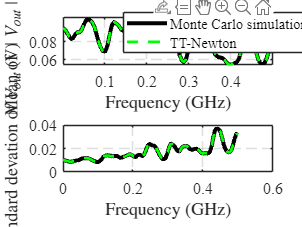

vout_mean0 = mean(abs(vouts));
vout_sigma0 = std((vouts));

vout_mean1 = mean(abs(vouts_Newton));
vout_sigma1 = std((vouts_Newton));


fpoints = linspace(0,5e8,100);
scale = 1e9;
f = figure(2);
subplot(2,1,1);
hold on
plot(fpoints/scale,vout_mean0,'k-','LineWidth',3);
plot(fpoints/scale,vout_mean1,'g--','LineWidth',2);
legend('Monte Carlo simulation','TT-Newton')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of $ \mid V_{out} \mid $ (V)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;


subplot(2,1,2);
hold on
plot(fpoints/scale,vout_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,vout_sigma1,'g--','LineWidth',2);
ylim([0.0 0.04])
grid on
ylabel('Standard devation of $ V_{out} $ (V)','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;


f.Position = [100 100 675 500];

pdf_freq_idx = 100;
figure(1)
histogram(abs(vouts(:,pdf_freq_idx)),50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N,edges] = histcounts(abs(vouts_Newton(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'b--','LineWidth',3)
[N,edges] = histcounts(abs(vouts_total2(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'r--','LineWidth',2)
[N,edges] = histcounts(abs(vouts_total3(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'c--','LineWidth',2)
% [N,edges] = histcounts(abs(vouts_GD(:,pdf_freq_idx)), 'Normalization', 'pdf');
% plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
% [N,edges] = histcounts(abs(vouts_ALS(:,pdf_freq_idx)), 'Normalization', 'pdf');
% plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
xlim([0.02 0.12])
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
legend('MC', 'TT-Newton','Total(m=2)','Total(m=3)','interpreter','LaTex');